# Enviroment representation

## BY MARC GUITART I CATERINA MOLL

The following pseudo code will help you to recreate the enviroment as Rosa Robot does.

Moreover will help you in understant all the transformation algebra needed to manage the information.

Keep in mind: 

a) Rosa Robot touch the fiducial and this allow to the system to know the the fiducial coordinates wrt RF {R}

b) From Dicom image you know the fiducial coordinates wrt RF {I}

c) Use a new RF {F} as an intermediate RF among both (Fiducial wrt {I} and Fiducial wrt {R})

d) Then you already have all the Transformation to given Tumor wrt RF{I} to know Tumor coordiantes wrt {R}

## Given enviroment

Given the table with the patient in an arbitrary pose. Use your previous deliverables.

In fact only fiducials are needed

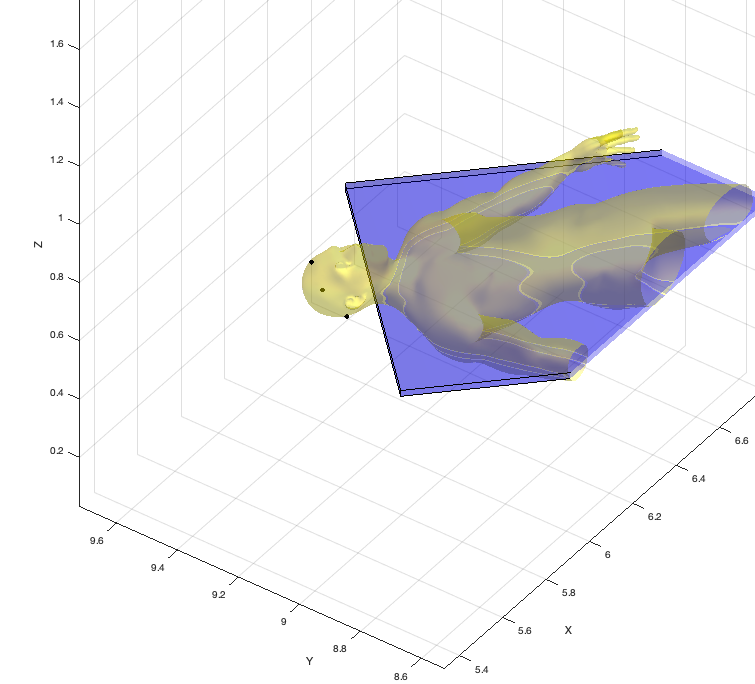

%put your code here

f_1 = eye(4);

f_1(1,4) = 0.0194;
f_1(2,4) = 0.1982-0.0238;
f_1(3,4) = 0.0448;

f_2 = eye(4);

f_2(1,4) = 0.1330;
f_2(2,4) = 0.1982-0.0251;
f_2(3,4) = 0.0910;

f_3 = eye(4);

f_3(1,4) = 0.0721;
f_3(2,4) = 0.1982-0.161;
f_3(3,4) = 0.1316;

tumor = eye(4);

tumor(1,4) = 0.0824;
tumor(2,4) = 0.1982-0.1379;
tumor(3,4) = 0.1078;


## Robot Frame wrt {U}

The Robot Rosa is located near by the patient 

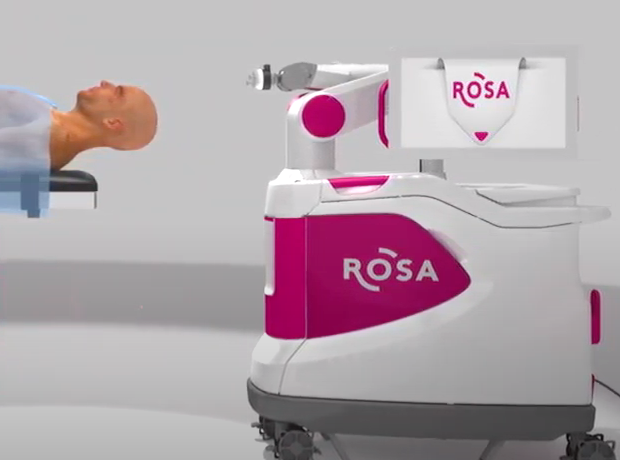

Locating the Robot. Understand the code

robot_loation=transl(5.75,9.75,0)*trotz(-pi/4)

robot_loation =     0.7071    0.7071         0    5.7500
   -0.7071    0.7071         0    9.7500
         0         0    1.0000         0
         0         0         0    1.0000


mdl_puma560;
p560.base=robot_loation

 
p560 = 
 
Puma 560 [Unimation]:: 6 axis, RRRRRR, stdDH, slowRNE            
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
base:    t = (5.75, 9.75, 0), RPY/xyz = (-45, 0, 0) deg          
 


p560.plot(qr,'zoom',1.5)
axis([5 6.5 8.8 10 0 1.8])

T_R_U=p560.base.T

T_R_U =     0.7071    0.7071         0    5.7500
   -0.7071    0.7071         0    9.7500
         0         0    1.0000         0
         0         0         0    1.0000


## Fiducial wrt {U}

To emulate the action of measuring the fiducial wrt Robot Frame use your fiducials coordinate wrt {U}.

% Declare your fiducial coordinates
F1= f_1(1:3,4)

F1 =     0.0194
    0.1744
    0.0448


F2= f_2(1:3,4)

F2 =     0.1330
    0.1731
    0.0910


F3= f_3(1:3,4)

F3 =     0.0721
    0.0372
    0.1316


## Transform compound needed

We will need the following Reference Frames: {U}, {R}, {F}, {I} 

and the Following Transformation: $ {}_R^U{T,{}_F^R{T,{}_I^F{Tand{}_I^R{T$to correctly face the problem.

It is clear that we will need the transformation Image to Robot, i.e. ${}_I^R{T$ to correctly make the tumor surgery.

Remeber the doctor, based on the Dicom image locate the Tumor (i.e Reference Image {I}) .

## Fiducial in RF Robot {R}

Notice: You have fiducial in RF {U}={A } and you want it in RF{R}={B} ... So  ${}^BP = {}_B^A{T^{ - 1}}{}^AP$

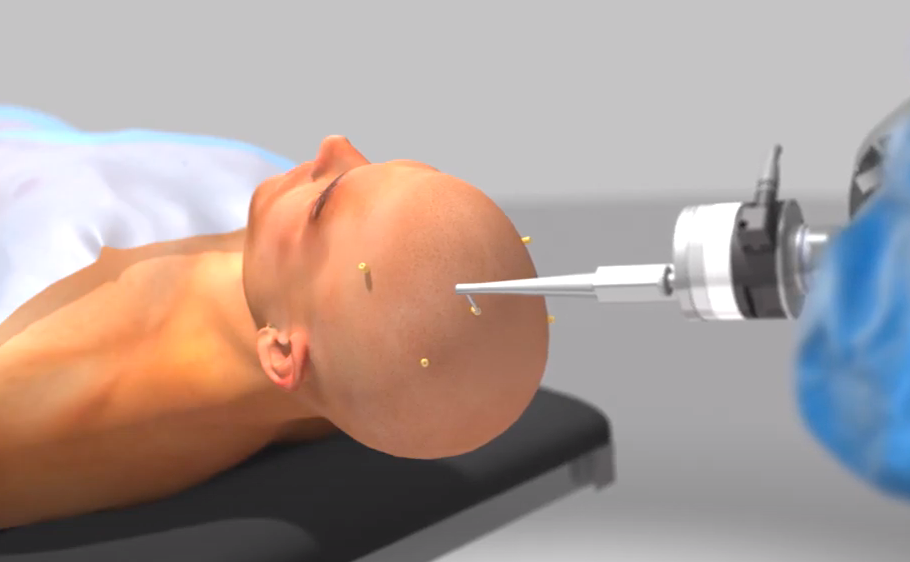

Fi_R=inv(T_R_U)*[F1 F2 F3;ones(1,3)]

Fi_R =     2.7188    2.8001    2.8531
  -10.8231  -10.7437  -10.8829
    0.0448    0.0910    0.1316
    1.0000    1.0000    1.0000


## RF Fiducial {F} wrt RF {R}

It is needed to use an auxiliary Reference Frame formed by the three fiducials becouse they are measured by the Robot using the teach Tool (See above section) and the Computed Tomography (Dicom images).

We will use the fiducials in RF {R}

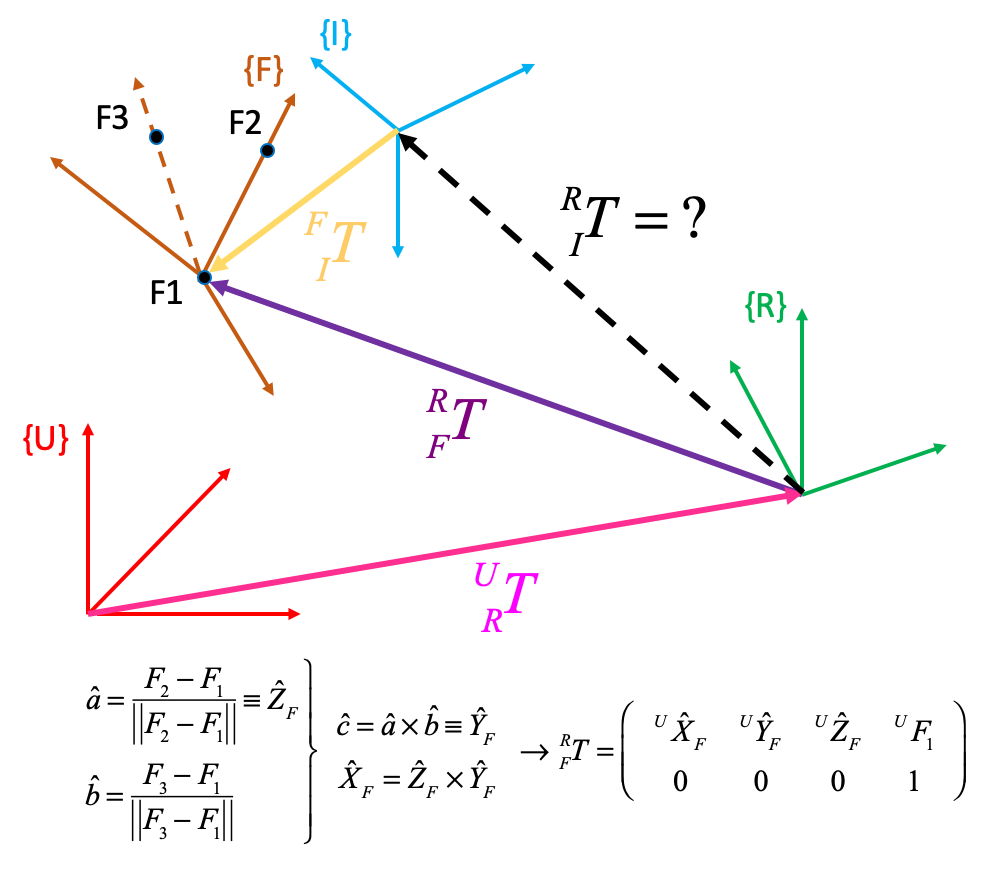

### Orientation wrt {R}

As a matter the example. 

Yf = (Fi_R(1:3,2)-Fi_R(1:3,1))/norm(Fi_R(1:3,2)-Fi_R(1:3,1));
b  = (Fi_R(1:3,3)-Fi_R(1:3,1))/norm(Fi_R(1:3,3)-Fi_R(1:3,1));
Zf = cross(Yf,b)/norm(cross(Yf,b));
Xf = cross(Yf,Zf)/norm(cross(Yf,Zf));

### Hand made frame description   

${}_F^R{T$ take the Fiducial 1 as ${}^A{P_{BORG}}$ in our case A is RF{R}

T_F_R = [[Xf;0] [Yf;0] [Zf;0] [Fi_R(:,3)]]

T_F_R =    -0.5317    0.6625    0.5276    2.8531
    0.7607    0.6475   -0.0464  -10.8829
   -0.3724    0.3767   -0.8482    0.1316
         0         0         0    1.0000


Checking the rotation matrix

The determinan must be 1

det(T_F_R(1:3,1:3))

ans = 1

## RF Fiducial {F} wrt RF {U}

The answer to this question is ${}_F^U{T={}_R^U{T{}_F^R{T$

We needed  ${}_F^U{T$to draw it in RF {U}

T_F_U=T_R_U*T_F_R

T_F_U =     0.1619    0.9263    0.3403    0.0721
    0.9139   -0.0106   -0.4059    0.0372
   -0.3724    0.3767   -0.8482    0.1316
         0         0         0    1.0000


trplot(T_F_U,'Frame','F','color', 'b','length',0.4)

## Fiducials wrt {I} 

Taking data from Dicom images

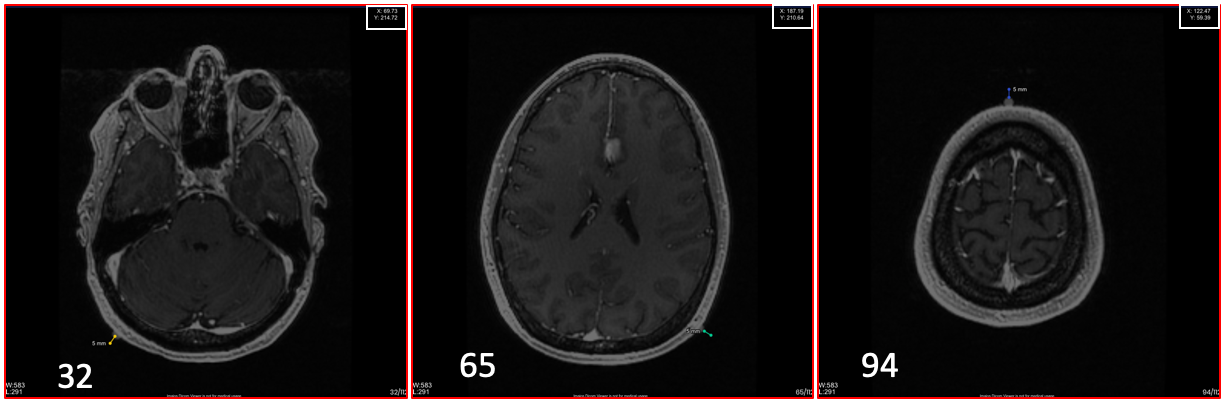

pitch =1.4; % Pitch among slices 
F1D = [f_1(1,4) f_1(2,4) 0.032*pitch]'; %image #32
F2D = [f_2(1,4) f_2(2,4) 0.065*pitch]'; %image #65
F3D = [f_3(1,4) f_3(2,4) 0.094*pitch]'; %image #94
Tumor=[tumor(1,4) tumor(2,4) 0.078*pitch]'; %image #78

## Visualizing fiducials and tumor

Use your previous deliverables

### Image Frame 

Plotting Image Reference Frame at origen of Reference Frame Univers {U}

trplot(eye(3),'Frame','I','color', 'r','length',0.4, 'arrow','width',0.4)
hold on
axis([-0.1 0.5 -0.1 0.5 -0.1 0.6])
view (-15,-65) % For better understanding

### Fiducials and tumor in {I} 

We use a sphere to represent a fiducial

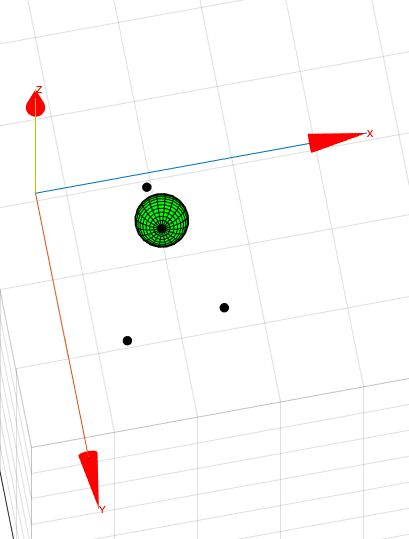

% put your code here

hold on
[X,Y,Z] = sphere;
r=0.005;% 5 mm

surf(f_1(1,4)+X*r,f_1(2,4)+Y*r,f_1(3,4)+Z*r,'FaceColor',[1 0 0])
surf(f_2(1,4)+X*r,f_2(2,4)+Y*r,f_2(3,4)+Z*r,'FaceColor',[0 1 1])
surf(f_3(1,4)+X*r,f_3(2,4)+Y*r,f_3(3,4)+Z*r,'FaceColor',[0 0 1])

hold on

[X,Y,Z] = sphere;
r = 0.0173;% 15 mm
surf(tumor(1,4)+X*r,tumor(2,4)+Y*r,tumor(3,4)+Z*r,'FaceColor',[0 1 0])
p560.plot(qr,'zoom',1.5)


triangle = [f_1(1:3,4), f_2(1:3,4), f_3(1:3,4)];


## T_F_I - Frame Description 

As we mention before It is needed to use the Fiducial as auxiliary Reference Frame 

Extracted from the triangle F1D - F2D - F3D

Same procedure as before with the fiducial in RF {U}

### Orientation 

YfD = (F2D - F1D) / norm(F2D - F1D);
bD = (F3D - F1D) / norm(F3D - F1D);
ZfD = cross(YfD, bD) / norm(cross(YfD, bD));
XfD = cross(YfD, ZfD) / norm(cross(YfD, ZfD));

### Frame Description  

${}_F^I{T$ take the Fiducial 1 as ${}^A{P_{BORG}}$ in our case A is RF{I}

T_F_I = [[XfD;0] [YfD;0] [ZfD;0] [F3D;1]]

T_F_I =     0.1619    0.9263    0.3403    0.0721
    0.9139   -0.0106   -0.4059    0.0372
   -0.3724    0.3767   -0.8482    0.1316
         0         0         0    1.0000


det(T_F_I)

ans = 1.0000

### Visualizing T_F_I

Fiducial Reference Frame wrt Reference frame {I} at origen of {U}

hold on
trplot(T_F_I,'Frame','F','color', 'b','length',0.4)

## RF Image {I} wrt RF {U}

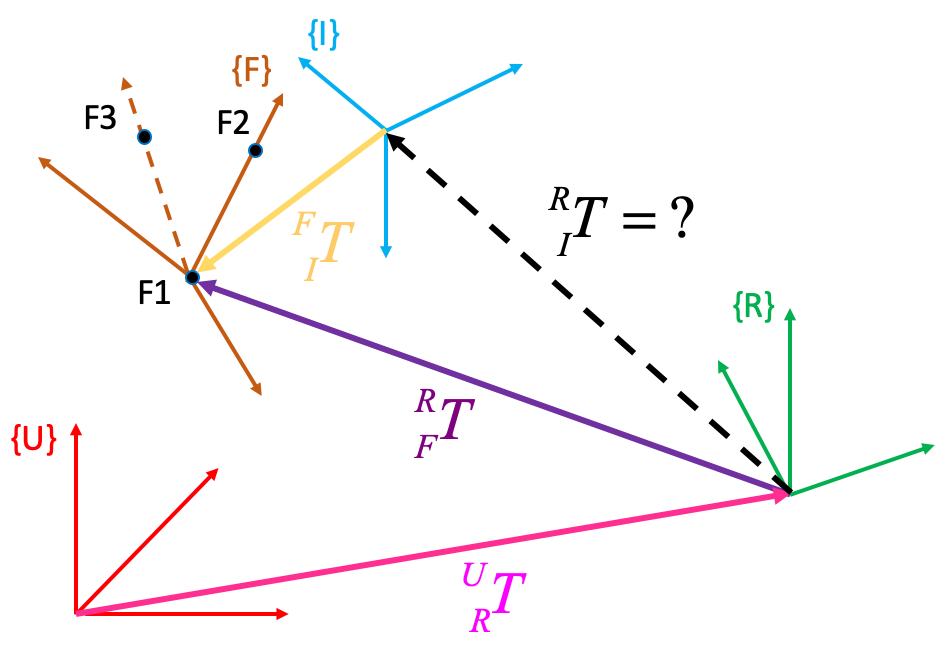

We have the Reference Frame {F} wrt {U} ${}_F^U{T={}_R^U{T{}_F^R{T$ and also ${}_F^I{T $, so ... ${}_I^U{T={}_F^U{T{}_F^I{T^{-1}$

T_I_U=T_F_U*inv(T_F_I)

T_I_U =     1.0000   -0.0000    0.0000   -0.0000
    0.0000    1.0000    0.0000   -0.0000
   -0.0000   -0.0000    1.0000    0.0000
         0         0         0    1.0000


Ckeck that ${}_I^U{T$ is coincident with the given Image Reference Frame 

hold on
trplot(T_I_U,'Frame','I','color', 'cyan','length',0.7)

## T_I_R System equation


$$ {}_I^U{T={}_F^U{T{}_F^I{T^{-1}={}_R^U{T{}_I^R{T\\
{}_I^R{T={}_R^U{T^{-1}{}_F^U{T{}_F^I{T^{-1}$$


hold on

T_I_R=inv(T_R_U)*T_F_U*inv(T_F_I)

T_I_R =     0.7071   -0.7071   -0.0000    2.8284
    0.7071    0.7071    0.0000  -10.9602
   -0.0000   -0.0000    1.0000    0.0000
         0         0         0    1.0000


%trplot(T_I_R,'Frame','I','color', 'r','length',0.5)

## Overall ckecking

### Fiducials in Robot Frame

As a matter of proof, ckeck that given Fiducials coordinates in Image Reference Frame we can obtain them in Robot Reference Frame

Fi_R

Fi_R =     2.7188    2.8001    2.8531
  -10.8231  -10.7437  -10.8829
    0.0448    0.0910    0.1316
    1.0000    1.0000    1.0000


### Fiducials in Univers Frame

As a matter of proof, ckeck that given Fiducials coordinates in Image Reference Frame we can obtain them in Univers Reference Frame.

Fi_R2=T_R_U*T_I_R*[[F1D F2D F3D];ones(1,3)]

Fi_R2 =     0.0194    0.1330    0.0721
    0.1744    0.1731    0.0372
    0.0448    0.0910    0.1316
    1.0000    1.0000    1.0000



AB = (triangle(1:3,1) - triangle(1:3,2)) / norm(triangle(1:3,1) - triangle(1:3,2)); 
CB = (triangle(1:3,3) - triangle(1:3,2)) / norm(triangle(1:3,2) - triangle(1:3,3)); 
Z_B = cross(CB, AB) / norm(cross(CB, AB));                                          
O_B_A = oa2r(AB, Z_B);                                                              
T_Fiducials_Ini = [O_B_A f_2(1:3,4); 0 0 0 1];
hold on


RF_U = transl(0,0,0);
T_U_R = transl(p560.base.t(1), p560.base.t(2), p560.base.t(3));
%T_U_I = transl(T_Caja_Rot_Fin(1,1),T_Caja_Rot_Fin(2,2),T_Caja_Rot_Fin(3,3));



trplot(RF_U, 'frame', 'RF_U', 'color', 'red', 'length', 0.4, 'text_opts', {'FontSize', 5});
trplot(T_U_R, 'frame', 'T_U_R', 'color', 'green', 'length', 0.4, 'text_opts', {'FontSize', 5});

%trplot(T_U_I, 'frame', 'T_U_I', 'color', 'b', 'length', 0.4, 'text_opts', {'FontSize', 7});

%trplot(T_Fiducials_Ini, 'length', 0.2, 'arrow', 'color', 'r');

## Summary

a) Rosa Robot touch the fiducial and this allow to the system to know the the fiducial coordinates wrt RF {R}

b) From Dicom image you know the fiducial coordinates wrt RF {I}

c) Use a new RF {F} as an intermediate RF among both (Fiducial wrt {I} and Fiducial wrt {R})

d) Then you already have all the Transformation to given Tumor wrt RF{I} to know Tumor coordiantes wrt {R}

e) You can draw tumor, containing box, human and table and you can represent all the RF's

## How I will ckeck 

Next Laboratory session I will give you the Rosa Robot information: i.e the Fiducials coordinates in RF {R}

and you will have to recreate all the enviroment. (containing box, human, table and all RF's)

There will be no second round, that is, I will mark your result.